# `Lista 3`

`Hubert Jackowski`

## `Układ Lotki-Volterry`

`Równanie Lotki-Volterry to model układu dynamicznego opisujący wzajemną zależność  rozmiarów populacji drapieżników i ofiar. Został on zaproponowany niezależnie przez dwóch  badaczy Vito Volterrę w 1926 oraz Alfreda James Lotkę w 1920 roku. [1]`

#### `MODEL`

`Figure 1: Matematyczny model układu Lotki-Volterry`

`Gdzie: x - populacja ofiar, y - populacja drapieżników, t - czas, a - częstość narodzin ofiar, b - częstość umierania ofiar, c - częstość narodzin drapieżników, d - częstość umierania drapieżników.`

def lotkaVolterra(dt: float, t: float, x0: float, y0: float, a: float, b: float, c: float, d: float):
    def _lotkaVolterra(state):
        x, y = state

        dx = (a - b * y) * x
        dy = (c * x - d) * y

        return np.array([dx, dy])

    num_steps = int(t / dt)

    states = np.empty((num_steps + 1, 2))
    states[0] = (x0, y0)
    for i in range(num_steps):
        states[i + 1] = states[i] + _lotkaVolterra(states[i]) * dt
    return states

`Figure 2: Realizacja modelu Lotki-Volterry za pomocą metody Eulera w języku Python`

def lotkaVolterra(dt: float, t: float, x0: float, y0: float, a: float, b: float, c: float, d: float):
    def _lotkaVolterra(state, _t, _a, _b, _c, _d) -> list:
        x, y = state

        dx = (_a - _b * y) * x
        dy = (_c * x - _d) * y

        return [dx, dy]

    args = (x0, y0)
    time = np.arange(0.0, t, dt)
    param = (a, b, c, d)
    return odeint(_lotkaVolterra, args, time, param)

`Figure 3: Realizacja modelu Lotki-Volterry za pomocą metody scipy.integrate.odeint w języku Python`

## `Układ Lorenza`

`Układ Lorenza to model układu dynamicznego opisujący zjawisko konwekcji termicznej w atmosferze. Uwzględznia on lepkość ośrodka, jego przewodnictwo cieplne oraz rozmiary ośrodka, w którym odbywa się proces. Zaproponowany został przez Edwarda Lorenza w 1963 roku. [2]`

#### `MODEL`

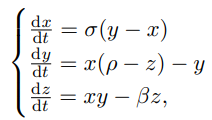

`Figure 4: Matematyczny model układu Lorentza`

`Gdzie:  σ – liczba Prandtla, charakteryzująca lepkość ośrodka; ρ – liczba Rayleigha, charakteryzująca przewodnictwo cieplne ośrodka; β – stała charakteryzująca rozmiary obszaru, w którym odbywa się przepływ konwekcyjny.`

def lorentz(dt: float, t: float, x0: float, y0: float, z0: float, sigma: float, beta: float, rho: float):
    def _lorentz(state):
        x, y, z = state
        dx = sigma * (y - x)
        dy = rho * x - y - x * z
        dz = x * y - beta * z
        return np.array([dx, dy, dz])

    num_steps = int(t / dt)

    states = np.empty((num_steps + 1, 3))
    states[0] = (x0, y0, z0)
    for i in range(num_steps):
        states[i + 1] = states[i] + _lorentz(states[i]) * dt
    return states


`Figure 5: Realizacja modelu Lorentza za pomocą metody Eulera w języku Python`

def lorentz(dt: float, t: float, x0: float, y0: float, z0: float, sigma: float, beta: float, rho: float):
    def _lorenz(state, _t, _sigma, _beta, _rho):
        x, y, z = state

        dx = _sigma * (y - x)
        dy = x * (_rho - z) - y
        dz = x * y - _beta * z

        return [dx, dy, dz]

    args = (x0, y0, z0)
    time = np.arange(0.0, t, dt)
    param = (sigma, beta, rho)
    return odeint(_lorenz, args, time, param)

`Figure 6: Realizacja modelu Lorentza za pomocą metody scipy.integrate.odeint w języku Python`

#### `OBSERWACJE`

`Poniżej przedstawione wykresy są wynikami symulacji dla wartości parametrów modelu Lotki-Volterry: {a = 1.2, b = 0.6, c = 0.3, d = 0.8, x(0) = 2, y(0) = 1} oraz modelu Układu Lorenza: {σ = 10, β = 8/3 i ρ = 28, x(0) = y(0) = z(0) = 1} dla czasu t ∈ [0, 25] i zmiennego dt ∈ {0.001, 0.01, 0.02}.`

#### `WNIOSKI`

`[1] J.D. Murray: Wprowadzenie do Biomatematyki. Warszawa: Wydawnictwo Naukowe PWN, 2006.`

`[2] Edward N. Lorenz: Deterministic Nonperiodic Flow. „J.Atmos.Sci.”. 20 (2), s. 130–141, 1963.`